#                                          Statistica Multivariata - Prof. Maurizio Vichi

#                                                                   Homework 2

#                                                              Alessandro Sottile

#                                                                 a.a. 2020-2021

# Esercizio 0

Rinominare il file "Homework 2.mlx" con "cognome_Multivariata2.mlx". 

Gli esercizi assegnati di seguito dovranno essere svolti mediante questo strumento (Live Script) che permette contemporaneamente di scrivere parti di testo e codice nella stessa schermata e di elaborarli entrambi in un unico pdf.

Per salvare questo file come pdf: "Save" --> "Export to PDF...".

Per inserire parti di testo usare il comando "Text", per quelle di codice il comando "Code".

I passaggi effettuati per la risoluzione degli esercizi assegnati dovranno essere giustificati sia riportando il codice che commentando i risultati ottenuti e dandone una propria interpretazione.

# Esercizio 1

Per i seguenti punti, si faccia riferimento al dataset utilizzato nell'Homework 1. 

1. Creare una nuova matrice di dimensione $\left(107\;x\;6\right)$ selezionando le 6 variabili scelte al punto 4 dell'Esercizio 1 dell'Homework 1. ATTENZIONE: Se tra le variabili scelte ci sono quelle ricodificate ai punti 6 e 7 dell'Esercizio 1 dell'Homework 1, fare riferimento alle variabili originarie.

load("Dataset Qualità della Vita")
t = X(:,[7 13 21  24 29 37]); 
Nomi_t = {'Spesa pro capite in viaggi/turismo'; 'Startup innovative'; 'Indice climatico di escursione termica'; 
    'Indice di vecchiaia'; 'Durata media dei processi'; 'Indice di sportività'};

t rapresenta la matrice usata nell'homework1. Nel vettore Nomi_t invece sono inserite a cosa corrispondono le variabili citate.

2. Costruire la matrice di correlazione con il dataset ottenuto al punto 1 (usare la funzione scritta per risolvere        il punto 2 dell'Esercizio 1 dell'Homework 1). Rappresentare graficamente la matrice di correlazione mediante una  heatmap e commentare le relazioni tra le variabili selezionate. 

[~,~,Rt]=Funzione1(t);
h1=heatmap(Rt)

h1 =   HeatmapChart with properties:

        XData: {6×1 cell}
        YData: {6×1 cell}
    ColorData: [6×6 double]

  Show all properties


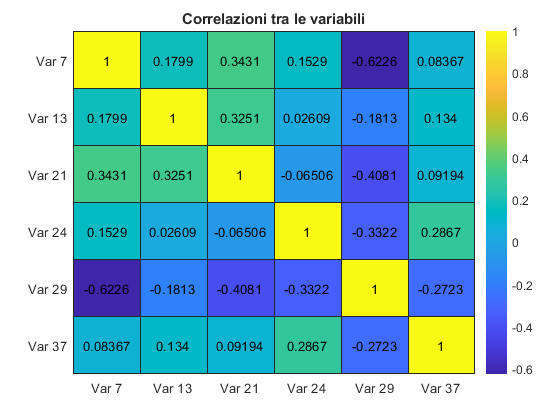

h1.Title = 'Correlazioni tra le variabili';
h1.Colormap = parula;
h1.CellLabelColor = 'k';
h1.YDisplayLabels = {'Var 7','Var 13','Var 21','Var 24','Var 29','Var 37'};
h1.XDisplayLabels = {'Var 7','Var 13','Var 21','Var 24','Var 29','Var 37'};

Dalla matrice di correlazione possiamo notare come per molte delle coppie vi sia un grado di correlazione positiva/negativa molto poco intenso, quasi inesistente addirittura, come per esempio la coppia formata dalle variabili 24 e 13. Per altre, invece, troviamo un grado di correlazione, legermente pù alto, ad esempio la coppia Var 21 e Var 13, le quali risultano godere di un livello appena apprezzabile di correlazione positiva.

Solo due coppie possiedono un livello di correlazione almeno considerevole:la coppia formata da Var 21 e Var 29, e quella formata da Var 7 e Var 29;  le ultime due variabili addirittura possono beneficiare di un intenso livello di correlazione negativa.

3. È possibile evidenziare dei clusters mediante la rappresentazione fatta al punto 4 dell'Esercizio 1 dell'Homework 1? Se sì, continuare le analisi con i seguenti punti; altrimenti, modificare opportunamente la matrice creata al punto 1 selezionando una variabile per ciascuna dimensione (al fine di individuare una struttura di clustering nei dati).

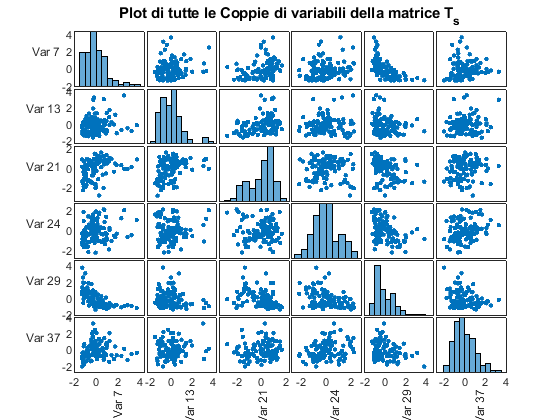

T_s=zscore(t);
[S,AX,BigAx,H,HAx] = plotmatrix(T_s);
ylabel(AX(1,1),'Var 7','Rotation',0,'HorizontalAlignment','right');
ylabel(AX(2,1),'Var 13','Rotation',0,'HorizontalAlignment','right');
ylabel(AX(3,1),'Var 21','Rotation',0,'HorizontalAlignment','right');
ylabel(AX(4,1),'Var 24','Rotation',0,'HorizontalAlignment','right');
ylabel(AX(5,1),'Var 29','Rotation',0,'HorizontalAlignment','right');
ylabel(AX(6,1),'Var 37','Rotation',0,'HorizontalAlignment','right');
xlabel(AX(end,1),'Var 7','Rotation',90,'HorizontalAlignment','right');
xlabel(AX(end,2),'Var 13','Rotation',90,'HorizontalAlignment','right');
xlabel(AX(end,3),'Var 21','Rotation',90,'HorizontalAlignment','right');
xlabel(AX(end,4),'Var 24','Rotation',90,'HorizontalAlignment','right');
xlabel(AX(end,5),'Var 29','Rotation',90,'HorizontalAlignment','right');
xlabel(AX(end,6),'Var 37','Rotation',90,'HorizontalAlignment','right');
title(BigAx,'Plot di tutte le Coppie di variabili della matrice T_s');

Analizzando il grafico, ci si accorge che le variabili selezionate non hanno sufficiente potere discriminante per identificare i cluster. Si devono quindi selezionare altre variabili per cercare di migliorare la situazione, per queste ragioni definisco la nuova matrice Mod.

Mod =  X(:,[4 10 19  25 29 42]) ;
Mod_s=zscore(Mod);
Nomi_Mod = {'Consumi'; 'Tasso di disoccupazione giovanile'; 'I city rate'; 
    'Saldo migratorio interno'; 'Durata media dei processi'; 'Onlus'};

Il vetore Nomi_Mod contiene il nome delle nuove variabili scelte.

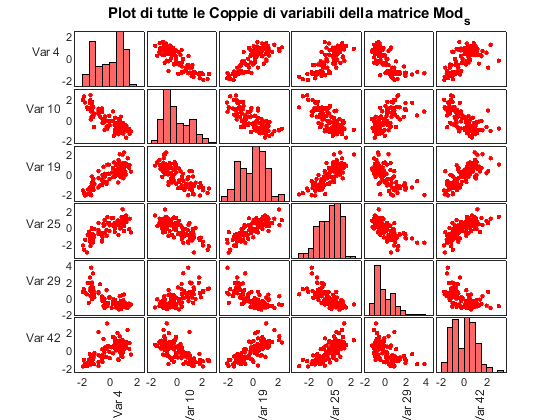

[S,AX,BigAx,H,HAx] = plotmatrix(Mod_s);
ylabel(AX(1,1),'Var 4','Rotation',0,'HorizontalAlignment','right');
ylabel(AX(2,1),'Var 10','Rotation',0,'HorizontalAlignment','right');
ylabel(AX(3,1),'Var 19','Rotation',0,'HorizontalAlignment','right');
ylabel(AX(4,1),'Var 25','Rotation',0,'HorizontalAlignment','right');
ylabel(AX(5,1),'Var 29','Rotation',0,'HorizontalAlignment','right');
ylabel(AX(6,1),'Var 42','Rotation',0,'HorizontalAlignment','right');
xlabel(AX(end,1),'Var 4','Rotation',90,'HorizontalAlignment','right');
xlabel(AX(end,2),'Var 10','Rotation',90,'HorizontalAlignment','right');
xlabel(AX(end,3),'Var 19','Rotation',90,'HorizontalAlignment','right');
xlabel(AX(end,4),'Var 25','Rotation',90,'HorizontalAlignment','right');
xlabel(AX(end,5),'Var 29','Rotation',90,'HorizontalAlignment','right');
xlabel(AX(end,6),'Var 42','Rotation',90,'HorizontalAlignment','right');
title(BigAx,'Plot di tutte le Coppie di variabili della matrice Mod_s');
for i=1:6
H(i).EdgeColor = 'k';
H(i).FaceColor = 'r'; 
end
for i=1:6
    for j=1:6
        S(i,j).Color='r';
    end
end

Per cercare di migliorare la situazione, tramite vari tentativi, si è riusciti a modificare le scelte delle variabili da inserire, infatti controllando graficamente i mutamenti che avvenivano all'interno del plotmatrix, con il cambiamento di alcune variabili, quelle che rendevano più nitida la presenza dei cluster, erano candidate ad entrare nella matrice.

Per avere anche un supporto analitico riguardo l'inclusione della variabile, per ogni cambiamento  effettuato era importante andare a controllare come variava il valore della pseudoF, infatti ogni variabile che aumentava il valore della funzione obiettivo rispetto ai dati usati in precedenza, veniva inserita nella matrice, almeno fino alla comparsa di una migliore per quel dominio.

Con la nuova matrice si riesce ad intuire meglio la presenza dei cluster all'interno del plotmatrix, sembrerebbero essere due i cluster presenti nella struttura dei dati. Vediamo tramite il calcolo della pseudoF se l'intuizione sarà confermata.

4.** K-means:** si implementi il k-medie sulla matrice creata al punto 1 (o punto 3), scegliendo il numero ottimale di clusters sulla base della pseudo  F - F max o  F di Calinski Harabasz - mediante la funzione scritta in classe (laddove non si era presenti, scrivere una funzione che restituisca in output un vettore contenente i valori della pseudo F per un range di valori K). Quali variabili contribuiscono maggiormente alla classificazione? Commentare i risultati. ATTENZIONE: ricordandone le proprietà analizzate in classe, si applichi il k-means dopo una appropriata trasformazione dei dati.

[F] = pseudoF(Mod_s,1,10);

k-means: loopOtt=1, fOtt=636, iter=1
k-means: loopOtt=1, fOtt=235.894, iter=7
k-means: loopOtt=1, fOtt=189.663, iter=4
k-means: loopOtt=4, fOtt=189.615, iter=7
k-means: loopOtt=15, fOtt=187.592, iter=7
k-means: loopOtt=1, fOtt=167.349, iter=8
k-means: loopOtt=10, fOtt=167.238, iter=8
k-means: loopOtt=12, fOtt=165.37, iter=18
k-means: loopOtt=17, fOtt=164.925, iter=9
k-means: loopOtt=1, fOtt=167.552, iter=6
k-means: loopOtt=2, fOtt=152.534, iter=10
k-means: loopOtt=5, fOtt=150.799, iter=15
k-means: loopOtt=12, fOtt=147.826, iter=15
k-means: loopOtt=20, fOtt=147.684, iter=5
k-means: loopOtt=1, fOtt=139.426, iter=13
k-means: loopOtt=2, fOtt=135.839, iter=11
k-means: loopOtt=6, fOtt=135.237, iter=15
k-means: loopOtt=7, fOtt=133.858, iter=20
k-means: loopOtt=9, fOtt=133.617, iter=17
k-means: loopOtt=11, fOtt=133.204, iter=13
k-means: loopOtt=30, fOtt=133.134, iter=13
k-means: loopOtt=1, fOtt=128.888, iter=11
k-means: loopOtt=9, fOtt=126.099, iter=10
k-means: loopOtt=18, fOtt=125.405, iter=1

F

F =        Inf  178.0936  124.2972   98.0661   84.3156   76.2980   68.6454   66.6279   59.1447   55.8200


maxF = max(F(2:10))

maxF = 178.0936

find(F==maxF)

ans = 2

In questo modo è stato trovato il k che rende massima la funzione obiettivo della pseudoF, in questo caso k = 2 e quindi l'intuizione avuta analizzando il plotamtrix di Mod_s è corretta.

evalclusters(Mod_s,'kmeans','CalinskiHarabasz','Klist',[2:10])

ans =   CalinskiHarabaszEvaluation with properties:

    NumObservations: 107
         InspectedK: [2 3 4 5 6 7 8 9 10]
    CriterionValues: [178.1027 123.5824 97.8821 82.6810 75.7795 69.2556 64.3724 58.4934 50.4141]
           OptimalK: 2


Possiamo notare che anche la funzione evalclusters restituisce lo stesso valore di k riportato sopra.

[Ft] = pseudoF(T_s,1,10);

k-means: loopOtt=1, fOtt=636, iter=1
k-means: loopOtt=1, fOtt=463.047, iter=5
k-means: loopOtt=1, fOtt=399.976, iter=8
k-means: loopOtt=2, fOtt=395.21, iter=7
k-means: loopOtt=5, fOtt=389.976, iter=5
k-means: loopOtt=1, fOtt=344.462, iter=8
k-means: loopOtt=2, fOtt=339.241, iter=8
k-means: loopOtt=1, fOtt=339.303, iter=13
k-means: loopOtt=2, fOtt=306.386, iter=11
k-means: loopOtt=8, fOtt=306.032, iter=8
k-means: loopOtt=12, fOtt=304.124, iter=10
k-means: loopOtt=16, fOtt=303.557, iter=6
k-means: loopOtt=20, fOtt=302.764, iter=7
k-means: loopOtt=1, fOtt=278.981, iter=10
k-means: loopOtt=5, fOtt=276.11, iter=5
k-means: loopOtt=1, fOtt=280.362, iter=7
k-means: loopOtt=2, fOtt=263.483, iter=11
k-means: loopOtt=4, fOtt=263.413, iter=7
k-means: loopOtt=7, fOtt=257.949, iter=9
k-means: loopOtt=11, fOtt=256.133, iter=9
k-means: loopOtt=1, fOtt=255.71, iter=7
k-means: loopOtt=2, fOtt=253.694, iter=14
k-means: loopOtt=4, fOtt=237.978, iter=10
k-means: loopOtt=12, fOtt=236.529, iter=11
k-means: l

Ft;
maxFt = max(Ft(2:10));
find(Ft==maxF);
maxF

maxF = 178.0936

maxFt

maxFt = 39.2185

Il valore assunto dalla pseudoF in corrispondenza di un k fissato, può anche essere interpretato come una misura di diagnostica del modello, più è alta e più sarà grande la porzione di devianza speigata dalla devianza between.

E' interessante notare come il valore della psuedoF calcolato in corrispondenza di k = 2, usando però questa volta la matrice standardizzata T_s, sia molto inferiore rispetto a quello calcolato tramite Mod_s; si passa infatti da un valore di 39.22 ad uno di 178.0.9,  questo risultato rafforza l'dea che la nuova matrice Mod_s ha migliorato decisamente la divisione in cluster.

Si può il k-medie sulla matrice dei dati standardizzati, in quanto il k-medie è uno strumento che risente fortemente della differenza di scala tra le variabili.

[loop,U,f,iter] = kmeansVICHI(Mod_s,2,100)

k-means: loopOtt=1, fOtt=235.894, iter=6


loop = 1

U =      0     1
     1     0
     1     0
     1     0
     1     0
     1     0
     1     0
     0     1
     0     1
     0     1


f = 235.8937

iter = 1

U rappresenta la matrice di appartenenza, la quale identifica per ogni unità il cluster di appartenenza.

E' interessante studiare quali siano le variabili che influenzino maggiormente la classificazione ottenuta.Per compiere questa analisi, si parte osservando il plotmatrix di Mod_s realizzato nel punto 3.

Di notevole interesse dovrebbe essere studiare le distribuzioni delle  variabili riportate nella diagonale del grafico citato precedentemente, quelle che dovrebbero influenzare maggiormente la classificazione sono quelle che tendono ad avere una distribuzione plurimodale, in quanto  variabili con queste caratteristiche riescono a creare dei sottogruppi all'interno della popolazione studiata. La variabile che più di tutti corrisponde al requesito è la 4  ovvero Consumi.

Per avere anche un supporto analitico, si può calcolare il valore della pseudoF per ciascuna delle variabili, fissato il valore di k pari a 2.

La variabile che avrà maggior peso nella classificazione sarà quella con la pseudoF maggiore

for i=1:6;
    [gl(:,i)]=pseudoF(Mod_s(:,i),2,2);
end

k-means: loopOtt=1, fOtt=19.0751, iter=4
k-means: loopOtt=1, fOtt=25.9462, iter=4
k-means: loopOtt=1, fOtt=28.9442, iter=3
k-means: loopOtt=1, fOtt=29.3271, iter=4
k-means: loopOtt=1, fOtt=33.1721, iter=6
k-means: loopOtt=1, fOtt=29.5966, iter=2


gl'

ans =   478.4829
  323.9643
  279.5335
  274.5127
  230.5225
  271.0569


Analizzando il vettore gl , si capisce come la variabile 4 sià quella più importante per la classificazione, confermando l'ipotesi.

Inoltre nello scatterplot tra la variabile 4 e la 42 risulta essere ben apprezzabile la divisione effettuata.

X_Mean = pinv(U)*Mod_s

X_Mean =     0.6759   -0.5912    0.6232    0.6154   -0.5699    0.5781
   -1.1322    0.9902   -1.0438   -1.0308    0.9545   -0.9684



gs1= gscatter(Mod_s(:,1),Mod_s(:,6),U)

gs1 =   2×1 Line array:

  Line    (0,1)
  Line    (1,0)


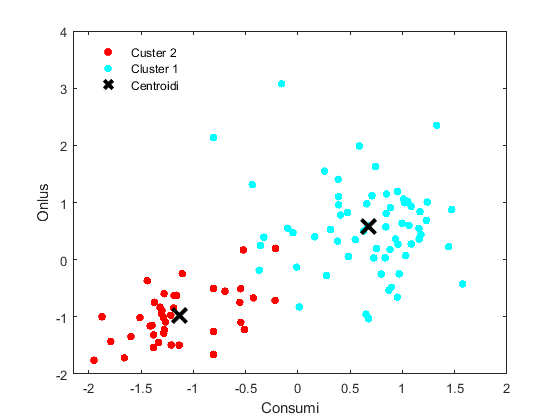

xlabel('Consumi')
ylabel('Onlus')
hold on
plot(X_Mean(:,1),X_Mean(:,6),'kx','MarkerSize',15,'LineWidth',3) 
legend('Custer 2','Cluster 1','Centroidi','Location','northwest')

E' interessante notare come i centroidi non siano valori realmente osservati, ma solo risultati teorici ottenuti con la media condizionata.

5.** K-medoid: **applicare il k-medoide sulla matrice creata al punto 1 (o punto 3) e con il numero ottimale di clusters scelto al punto 4, mediante la relativa funzione esistente in MATLAB. Commentare i risultati e confrontarli con quelli del punto 4, dopo aver calcolato la matrice di confusione (ATTENZIONE al label switching) e l'Adjusted Rand Index (ARI). ATTENZIONE: si applichi il k-medoide dopo una appropriata trasformazione dei dati.

Bisogna implementare il k-medoide  sulla matrice dei dati standardizzati, in quanto è uno strumento che non gode della proiprietà di invarianza di scala.

[idx,C,sumd,D,midx,info] = kmedoids(Mod_s,2)

idx =      1
     2
     2
     2
     2
     2
     2
     1
     1
     1


C =    -1.1884    1.3254   -1.0194   -1.1149    1.1387   -0.8463
    0.8441   -0.4575    0.7428    0.5035   -0.2473    0.8052


sumd =   104.1063
  153.6926


D =     2.1686   29.2520
   12.3577    2.7977
   13.2849    0.9982
   19.9293    1.2810
   17.1733    1.1956
   12.4679    1.1695
   14.6841    4.5183
    1.0335   16.3945
    1.9844    8.6816
    1.1615   14.4292


midx =     88
    87


info = struct with fields:
        algorithm: 'pam'
            start: 'plus'
         distance: 'sqeuclidean'
       iterations: 3
    bestReplicate: 1


I = eye(107);
m= I(idx,:);
Mt=m(:,[1 2]);
K = 2;
CU = zeros(K);
    for k = 1:K
        for g = 1:K
             CU(k,g) = sum((U(:,k)-Mt(:,g)).^2); 
        end
    end
    [PrU,unfeasU,DDU] = bghungar(-CU);
    Mt = Mt(:,PrU)

Mt =      0     1
     1     0
     1     0
     1     0
     1     0
     1     0
     1     0
     0     1
     0     1
     0     1


Partizione_Medoidi=sum(Mt)

Partizione_Medoidi =     68    39


Partizione_Centroidi=sum(U)

Partizione_Centroidi =     67    40


Ho ottenuto i due vettori contenenti le frequenze assolute dei cluster.

ConfMatr1=Mt'*U 

ConfMatr1 =     67     1
     0    39


Tramite la matrice di confusione, si nota che vi è stata una differenza di classificazione per solamente 1 variabile.

Le due partizioni trovate sembrano quasi coincidere.

6.** Clustering gerarchico: **applicare i 4 metodi di clustering gerarchico studiati e rappresentarli graficamente mediante un dendrogramma. ATTENZIONE: si applichino i metodi di clustering gerarchico dopo una appropriata trasformazione dei dati.

Mod_Dist=squareform(pdist(Mod_s));

Tramite la trasformazione, è stata ottenuta una matrice delle distanze quadrate, questo è necessario per poter applicare i metodi del clustering gerarchico.

Metodo legame medio:

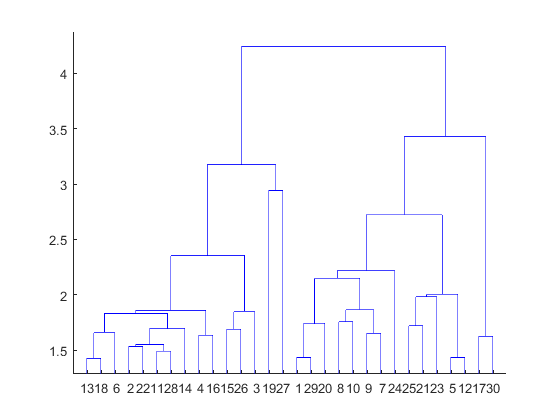

figure()
[Up1,A1,B1,levfus1,of1] = upgma(Mod_Dist,1);
dendrogram([A1 B1 levfus1])

Metodo legame semplice:

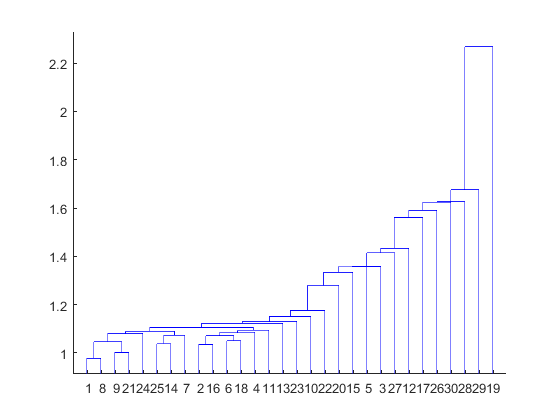

[Up2,A2,B2,levfus2,of2] = upgma(Mod_Dist,2);
dendrogram([A2 B2 levfus2])

Metodo legame completo:

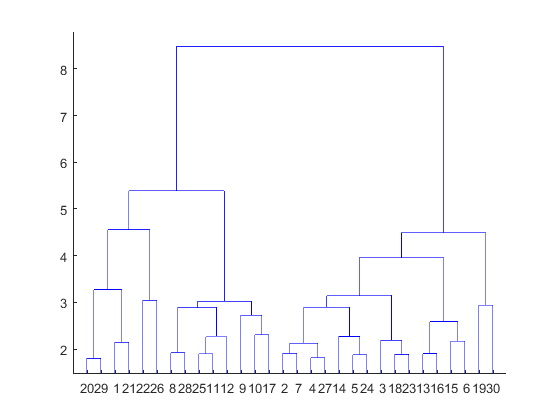

[Up3,A3,B3,levfus3,of3] = upgma(Mod_Dist,3);
dendrogram([A3 B3 levfus3])

Metodo di Ward:

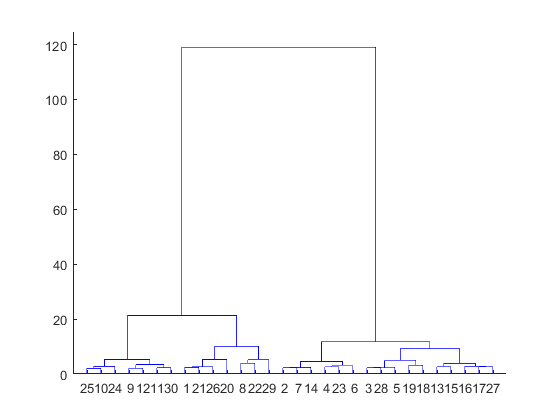

[Up4,A4,B4,levfus4,of4] = upgma(Mod_Dist,4);
dendrogram([A4 B4 levfus4])

7. Scegliere uno dei metodi implementati al punto 6 ed individuare il numero di clusters omogenei con il relativo dendrogramma. Costruire la matrice di appartenenza a partire dalla partizione che si otterrebbe con il metodo di clustering gerarchico scelto se si tagliasse il dendrogramma in corrispondenza del suddetto numero di clusters omogenei (ATTENZIONE: si vedano gli output e gli input della funzione *dendrogram;* con il secondo output è possibile ottenere il vettore di classificazione passando in input il numero di clusters omogenei individuati nel dendrogramma*)*. Calcolare la matrice di confusione tra la partizione ottenuta e quella risultante dal k-medie implementato al punto 4.

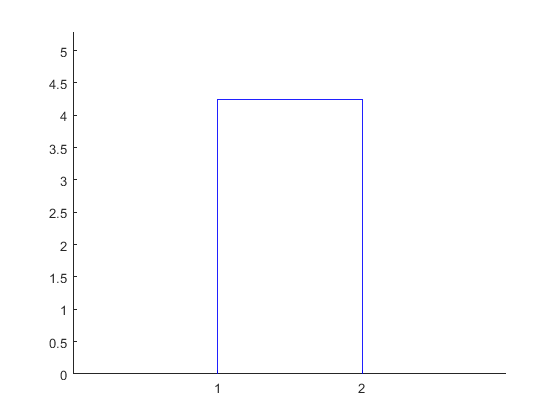

T =      1
     2
     2
     2
     2
     2
     2
     1
     1
     1


figure()
[~,T,~]= dendrogram([A1,B1,levfus1],2)

ho deciso di usare il metodo del legame semplice

Us=eye(size(Mod_s,1),2);
Us=Us(T,:);
K = 2;
CU = zeros(K);
    for k = 1:K
        for g = 1:K
             CU(k,g) = sum((U(:,k)-Us(:,g)).^2); 
        end
    end
    [PrU,unfeasU,DDU] = bghungar(-CU);
    Us = Us(:,PrU)

Us =      0     1
     1     0
     1     0
     1     0
     1     0
     1     0
     1     0
     0     1
     0     1
     0     1


Freq_ass_Gerarchico=sum(Us) 

Freq_ass_Gerarchico =     61    46


Us rappresenta la matrice di appartenenza, costruita tramite il clustering gerarchico.

Freq_ass_Gerarchico è un vettore contenente le frequenze assolute riguardo i due cluster.

ConfMatr2=Us'*U 

ConfMatr2 =     61     0
     6    40


Tramite l'imput grafico della matrice di confusione, si nota che vi è stata una differenza di classificazione per 6 variabili.

AdjRI=mrand(ConfMatr2) 

AdjRI = 0.7862

Il valore ottenuto da questo indice identifica la buona divisione effettuata.

8.** ACP: **aggiungere un'altra variabile per dominio al dataset costruito al punto 1 (o punto 3). Individuare le componenti principali di questo nuovo dataset, scegliendone il numero. Commentare i risultati e rappresentare le unità (e le variabili) sulle prime due componenti principali.

X_Agg=X(:,[1 4 8 10 16 19 22 25 29 31 41 42])

X_Agg = 	1.0e+04 *

    1.1756    0.1374    0.0009    0.0049    3.2632    0.0225    0.0032   -0.0004    0.0472    0.1997    0.0040    0.0164
    2.3301    0.2722    0.0010    0.0032    5.0410    0.0402    0.0029   -0.0000    0.0180    0.2155    0.0046    0.0406
    2.5152    0.2503    0.0010    0.0030    4.9945    0.0457    0.0038    0.0000    0.0246    0.2585    0.0018    0.0531
    3.1792    0.2725    0.0010    0.0018    5.8822    0.0468    0.0030   -0.0000    0.0129    0.2217    0.0039    0.0497
    2.1330    0.2666    0.0011    0.0018    4.7578    0.0465    0.0031    0.0000    0.0189    0.2319    0.0045    0.0406
    2.1485    0.2493    0.0012    0.0024    4.6925    0.0425    0.0043   -0.0001    0.0326    0.2259    0.0011    0.0584
    2.2114    0.2641    0.0011    0.0022    4.1373    0.0417    0.0024    0.0001    0.0181    0.1799    0.0043    0.0230
    2.1011    0.1616    0.0010    0.0031    2.7618    0.0297    0.0040   -0.0003    0.0548    0.2576    0.0021    0.0263
    1.7506  

X_AggS=zscore(X_Agg)

X_AggS =    -1.2766   -1.7899   -0.6658    1.7895   -1.2059   -2.0388    0.1581   -1.3705    0.7588   -0.6839    0.4907   -1.4316
    0.2456    0.8343    0.0945    0.3892    0.4414   -0.1986   -0.5956    0.1628   -0.9385   -0.4122    0.9479    0.0303
    0.4896    0.4080   -0.2096    0.2915    0.3983    0.3725    1.3513    0.3758   -0.5522    0.3267   -1.0174    0.7811
    1.3651    0.8402   -0.1336   -0.7425    1.2207    0.4900   -0.2606    0.1628   -1.2301   -0.3063    0.4293    0.5734
   -0.0143    0.7253    0.7027   -0.7343    0.1790    0.4578   -0.2397    0.3758   -0.8851   -0.1314    0.8796    0.0303
    0.0061    0.3885    1.3870   -0.2296    0.1185    0.0417    2.3352   -0.0502   -0.0910   -0.2334   -1.4336    1.1008
    0.0891    0.6766    0.7027   -0.3680   -0.3960   -0.0395   -1.5167    0.6313   -0.9333   -1.0253    0.7227   -1.0342
   -0.0563   -1.3188    0.3226    0.3729   -1.6704   -1.2951    1.8328   -0.9446    1.2015    0.3119   -0.7581   -0.8313
   -0.5185   -0.8068   

X_Agg rappresenta la nuova matrice ottenuta, prima di applicarla per l'ACP la standardizzo in quanto il metodo non è invariante rispetto ai cambiamenti di scala.

[coeff,score,latent,~,explained,~]=pca(X_AggS);

Esistono 3 metodi per scegliere le componenti principali:

Con il primo metodo si scelgono il numero di componenti principali, tante quanti sono gli autovalori maggiori della media, in questo caso il valore della media è pari a 1, in quanto i dati sono standardizzati.

size(find(latent>1),1)

ans = 3

in questo caso il numero delle componenti deve essere pari a 3.

Ora proviamo ad usare l'approccio della varianza spiegata, dove si cerca il numero minimo di elementi del vettore explained, che sommati riescano a spiegare almeno il 70% della varianza totale.

sum(explained(1:4))

ans = 82.4475

Anche in questo caso, il numero di componenti da usare risulta essere pari a 3.

Infine si può provare anche con il metodo grafico

p = plot(latent)

p =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1 2 3 4 5 6 7 8 9 10 11 12]
              YData: [6.4794 1.4157 1.0852 0.9134 0.6717 0.3834 0.3280 0.2024 0.1852 0.1496 0.1032 0.0827]
              ZData: [1×0 double]

  Show all properties


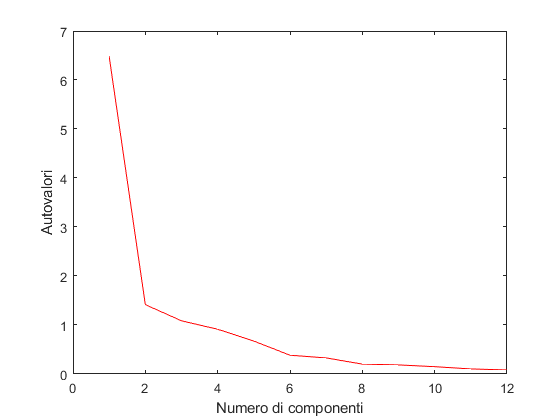

xlabel('Numero di componenti');
ylabel('Autovalori');
p.Color = 'red';

Il quale non risulta di nitida interpretazione, però avendo lo scopo di trovare il punto in cui la curva decresce meno rapidamente, possiamo intuire che ciò avverrà quando il numero scelto per le componenti sarà 3 oppure 4.

Avendo analizzato i vari metodi, si più  dichiarare che il numero delle componenti risulta essere pari a 3.

[coeff2,score2,latent2,~,explained2,~]=pca(X_AggS,"NumComponents",2)

coeff2 =     0.3163    0.2900
    0.3648   -0.0400
   -0.0291    0.2153
   -0.3452    0.0526
    0.3511    0.1576
    0.3623    0.1432
   -0.1592    0.3729
    0.3544   -0.0364
   -0.3192    0.0985
   -0.2001    0.5598


score2 =    -3.8896   -1.0307
    0.8627    0.1095
    0.7692    0.4085
    2.3343    0.5151
    1.2028    0.4119
    0.2866    0.4355
    0.8634   -0.9851
   -3.0197    0.0979
   -1.7600    0.1800
   -2.8545   -0.9635


latent2 =     6.4794
    1.4157
    1.0852
    0.9134
    0.6717
    0.3834
    0.3280
    0.2024
    0.1852
    0.1496


explained2 =    53.9954
   11.7971
    9.0434
    7.6116
    5.5972
    3.1952
    2.7337
    1.6870
    1.5435
    1.2465


label = {'Var 1','Var 2','Var 3','Var 4','Var 5','Var 6','Var 7','Var 8','Var 9','Var 10','Var 11','Var 12'};
h = biplot(coeff2(:, 1:2),'Scores',score2(:,1:2),'VarLabels',label)

h =   144×1 graphics array:

  Line    (varline)
  Line    (varline)
  Line    (varline)
  Line    (varline)
  Line    (varline)
  Line    (varline)
  Line    (varline)
  Line    (varline)
  Line    (varline)
  Line    (varline)
  Line    (varline)
  Line    (varline)
  Line    (varmarker)
  Line    (varmarker)
  Line    (varmarker)
  Line    (varmarker)
  Line    (varmarker)
  Line    (varmarker)
  Line    (varmarker)
  Line    (varmarker)
  Line    (varmarker)
  Line    (varmarker)
  Line    (varmarker)
  Line    (varmarker)
  Text    (varlabel)
  Text    (varlabel)
  Text    (varlabel)
  Text    (varlabel)
  Text    (varlabel)
  Text    (varlabel)
  Text    (varlabel)
  Text    (varlabel)
  Text    (varlabel)
  Text    (varlabel)
  Text    (varlabel)
  Text    (varlabel)
  Line    (obsmarker)
  Line    (obsmarker)
  Line    (obsmarker)
  Line    (obsmarker)
  Line   

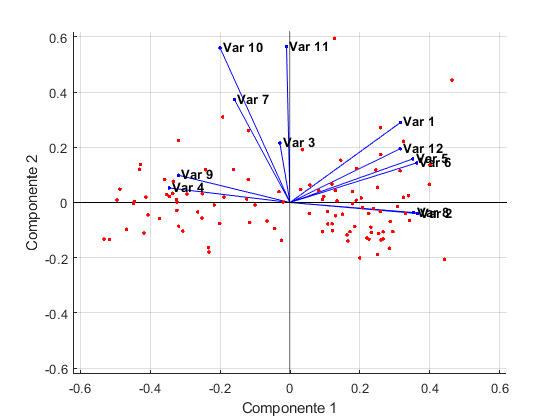

xlabel('Componente 1');
ylabel('Componente 2');
for k = 25:36
    h(k).FontWeight = 'bold';  
end

Osservando la matrice coeff2 , si può affermare che la componente 2 è influenzata prevalentemente dalle variabili 10 e 11, le quali hanno rispettivamente peso pari a 0.55 e 0.56. Passando invece alla componente 1, non si riesce a trovare la variabile che eserciti maggior peso sull'nfluenzare questa componente, infatti i valori della matrice coeff2 evidenziano il fatto che nessuna variabile ha un peso maggiore di 0.36,ma anzi quasi tutte tendando ad avere un valore simile a quest'ultimo.

9.** ACP "confermativa": **costruire un indicatore sintetico delle 42 variabili originali. Scegliere la prima componente principale per ogni dominio, ossia applicare una ACP separata per ciascun gruppo di variabili associate ad un dominio. Calcolare le 6 componenti principali $Y$ e valutarne le relazioni mediante la loro matrice di correlazione. Infine, calcolare una media delle 6 componenti principali per ciascuna provincia.

X_S=zscore(X);

Questa volta si parte dalla matrice dei dati originali X, ma per gli stessi motivi del punto precedente anche quest'ultima va standardizzata.

[B1,L1]=eigs(cov(X_S(:,1:7),1));
Y1=X_S(:,1:7)*B1(:,1)

Y1 =    -3.1355
    0.3043
    0.4842
    2.4227
    0.6577
   -0.7507
    0.2237
   -2.5696
   -1.1143
   -1.8098


[B2,L2]=eigs(cov(X_S(:,8:14),1));
Y2=X_S(:,8:14)*B2(:,1)

Y2 =     3.6682
   -0.8062
    0.5667
   -0.2494
   -1.5293
   -1.0829
   -0.4675
    1.0697
    1.3519
    1.9982


[B3,L3]=eigs(cov(X_S(:,15:21),1)); 
Y3=X_S(:,15:21)*B3(:,1)

Y3 =    -3.4634
   -0.7510
    1.0736
    2.0015
    1.0515
    0.2389
   -0.6432
   -2.0798
   -1.0394
   -2.3758


[B4,L4]=eigs(cov(X_S(:,22:28),1)); 
Y4=X_S(:,22:28)*B4(:,1)

Y4 =     0.4486
   -2.5050
   -0.5737
    0.7177
   -0.4134
   -1.8170
   -0.5408
   -0.5292
    1.1914
    1.9732


[B5,L5]=eigs(cov(X_S(:,29:35),1)); 
Y5=X_S(:,29:35)*B5(:,1)

Y5 =    -0.8793
   -1.2278
   -0.4327
   -2.1783
   -0.7066
   -0.4149
   -1.8876
    0.2159
    3.3589
    3.3670


[B6,L6]=eigs(cov(X_S(:,36:42),1)); 
Y6=X_S(:,36:42)*B6(:,1)

Y6 =    -2.2607
    0.8149
    1.5915
    1.2859
    0.5768
    3.5257
   -0.6608
   -1.1639
   -0.0576
   -1.2696



MatrComp= [Y1 Y2 Y3 Y4 Y5 Y6]

MatrComp =    -3.1355    3.6682   -3.4634    0.4486   -0.8793   -2.2607
    0.3043   -0.8062   -0.7510   -2.5050   -1.2278    0.8149
    0.4842    0.5667    1.0736   -0.5737   -0.4327    1.5915
    2.4227   -0.2494    2.0015    0.7177   -2.1783    1.2859
    0.6577   -1.5293    1.0515   -0.4134   -0.7066    0.5768
   -0.7507   -1.0829    0.2389   -1.8170   -0.4149    3.5257
    0.2237   -0.4675   -0.6432   -0.5408   -1.8876   -0.6608
   -2.5696    1.0697   -2.0798   -0.5292    0.2159   -1.1639
   -1.1143    1.3519   -1.0394    1.1914    3.3589   -0.0576
   -1.8098    1.9982   -2.3758    1.9732    3.3670   -1.2696


Tramite i codici elencati sopra, si riesce a calcolare l'ACP per ogni sottogruppo, e successivamente viene estratta la prima componente da ognuno di essi, in quanto per definizione sarà quella associata al più grande autovalore di ciascuna matrice analizzata. Infine si può creare la matrice contenenti le componenti principali.

h2 = heatmap(corrcoef(MatrComp))

h2 =   HeatmapChart with properties:

        XData: {6×1 cell}
        YData: {6×1 cell}
    ColorData: [6×6 double]

  Show all properties


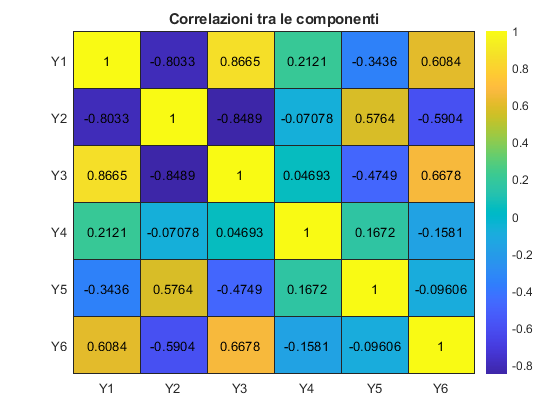

h2.Title = 'Correlazioni tra le componenti';
h2.Colormap = parula;
h2.CellLabelColor = 'k';
h2.YDisplayLabels = {'Y1','Y2','Y3','Y4','Y5','Y6'};
h2.XDisplayLabels = {'Y1','Y2','Y3','Y4','Y5','Y6'};

Analizzato il grafico ottenuto si notano diversi aspetti interessanti:  solamente tre coppie di componenti godono di una forte correlazione, negativa  per (Y1,Y2) e (Y2,Y3), mentre è positiva per (Y1,Y3).

Alcune coppie possiedono una correlazione discreta, che risulta essere positiva come nei (Y3,Y6),(Y1,Y6) ed(Y2,Y5), mentre negativa per (Y2,Y6), (Y3,Y6) ed (Y1,Y5).

Le coppie non citate possono essere valutate come tendenzialmente incorrelate.

MedieComponenti=mean(MatrComp,2);
Posizioni = (1:107)';
MedieComponentiInd= [MedieComponenti Posizioni];
Medie=sortrows(MedieComponentiInd,1, 'descend') ;

for i=1:107
    for j=1:107
        if j==Medie(i,2)
            Stampa(i,:)=[Medie(i,1) Province(j,1)];    
        end
    end
end
Classifica=Stampa(:,[2 1])

Classifica = 107×2 string array
    "Milano"             "2.8271" 
    "Roma"               "1.9177" 
    "Firenze"            "1.5813" 
    "Bologna"            "1.5534" 
    "Rimini"             "1.5353" 
    "Bolzano"            "1.3024" 
    "Napoli"             "1.0471" 
    "Verona"             "1.0123" 
    "Trento"             "1.009"  
    "Parma"              "0.98878"
    "Torino"             "0.84556"
    "Venezia"            "0.83368"
    "Ravenna"            "0.82859"
    "Modena"             "0.79971"
    "Monza e Brianza"    "0.68131"
    "Aosta"              "0.66667"
    "Trieste"            "0.65975"
    "Siena"              "0.62812"
    "Catania"            "0.62811"
    "Bari"               "0.61514"
    "Prato"              "0.59335"
    "Pisa"               "0.56366"
    "Brescia"            "0.55336"
    "Pescara"            "0.54209"
    "Bergamo"            "0.53838"
    "Forlì-Cesena"       "0.47989"
    "Ancona"             "0.45158"
    "Padova"           

Il vettore Classifica contiene la classifica di tutte le 107 province analizzate, ordinate in base alla media delle 6 componenti principali, la quale rappresenta una misura di qualità della vita.

**Il seguente esercizio non dovrà essere svolto da coloro che sosterranno il preappello e dovrà dunque essere inserito nella tesine di coloro che sosterranno l'esame ****dall****'appello di Gennario 2021.**

# Esercizio 2

- Salvare la matrice dei dati originari $X$in un file .csv.

- Importare in R il file .csv creato al punto 1 (Esercizio 2). Caricare la libreria *mclust* di R (laddove non ancora scaricata, installare il relativo pacchetto). 

- **Misture: **applicare il modello mistura al dataset originario (107x42) mediante la funzione "Mclust" del pacchetto m*clust. S*ulla base del BIC, quale modello è risultato il migliore e con quante componenti? Quale il secondo migliore? Commentare i risultati. ATTENZIONE: si veda l'Esercitazione del 27 novembre 2020 ([Esercitazione 27 novembre 2020)](https://drive.google.com/file/d/1ACRm-G35snrqIRecuNZ2gAobCSvJ8I9G/view).

- Implementare il k-means con il numero ottimale di clusters individuati da "Mclust" al punto 3 (Esercizio 2). Confrontare la classificazione risultante con quella ottenuta al punto 3 (Esercizio 2).

- **Analisi delle corrispondenze multiple: **ricodificare le seguenti variabili: "Consumi" (10%, 20%, 40%, 20%, 10%), "Tasso di disoccupazione giovanile" (5%; 20% ; 25%; 25% ;20%; 5%), "Spesa sociale degli enti locali per abitante"(15%, 35%, 35%, 10%, 5%), "Laureati per provincia di residenza" (15%, 35%, 35%, 10%, 5%), "Offerta culturale" (5%; 25%; 30%; 35%;5%). Applicare l’analisi delle corrispondenze multiple fissando il numero delle dimensioni pari a 2.

- Dopo aver quantificato le variabili calcolate al punto 5, applicare l’analisi categoriale delle componenti principali (CATPCA) alle variabili qualitative ricodificate al punto 5 e a quelle quantitative appena calcolate, fissando il numero di dimensioni a 2.

- Per il campione di 50 province estratto al punto 5 dell'Esercizio 1 dell'Homework 1, considerare le variabili relative ad un unico dominio e realizzare il biplot con $\alpha =\left\lbrace 0,\;0\ldotp 5,\;1\right\rbrace \ldotp$      

% Funzioni usate
%1

function[Xm,Sx,Rx]=Funzione1(A)
nrow=size(A,1);
u1=ones(nrow,1);
Xm=(pinv(u1)*A)';
Jc=eye(nrow)-(1/nrow)*ones(nrow);
Sx=1/nrow*A'*Jc*A;
D=diag(diag(Sx));
D=D.^0.5;
Rx=D^-1*Sx*D^-1;
end

%2
function [F] = pseudoF(X,minK,maxK)
for k = minK:maxK
    % [loopOtt,UOtt,fOtt,iterOtt]=kmeansVICHI(X,K,Rndstart);
    [~,U,~,~] = kmeansVICHI(X,k,30);
    Y = pinv(U)*X;
    F(k-minK+1) = (trace((U*Y)'*(U*Y))/trace((X-U*Y)'*(X-U*Y)))*((size(X,1)-k)/(k-1));
end
end